# 3D mapping

clear all

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 10);

% Specify sheet and range
opts.Sheet = "Test 1";
opts.DataRange = "A3:J2502";

% Specify column names and types
opts.VariableNames = ["Markers", "Displacement", "Force", "Time", "HARDNESS", "MODULUS", "XPosition", "YPosition", "S_2_P", "Depth"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "Markers", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Markers", "EmptyFieldRule", "auto");

% Import the data
excel_file = readtable("C:\Users\franc\Documents\Trabajo\Colaboraciones\Andrés\HFQP_test_75x75.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
excel_file

excel_file = 2500×10 table
    Markers    Displacement     Force      Time     HARDNESS    MODULUS    XPosition    YPosition    S_2_P     Depth 
    _______    ____________    _______    ______    ________    _______    _________    _________    ______    ______

      ""          1276.9       -3.0083    16.328     7.5792     228.77         0         73.485      7139.8     192.2
      ""          1277.9       -3.0102    17.489      7.031     238.54         0         71.961      8240.8    197.87
      ""          1277.4       -3.0102    18.667     7.1459      233.9         0         70.485      7852.9     196.8
      ""          1274.2       -3.0102    

Eliminate rows that contain NaN values in HARDNESS or MODULUS columns.

rowswithNaN=isnan(excel_file.HARDNESS) | isnan(excel_file.MODULUS);
cleandata=excel_file(~rowswithNaN,:);
% Eliminar la primera fila (encabezados)
cleandata(1, :) = [];


Histograms

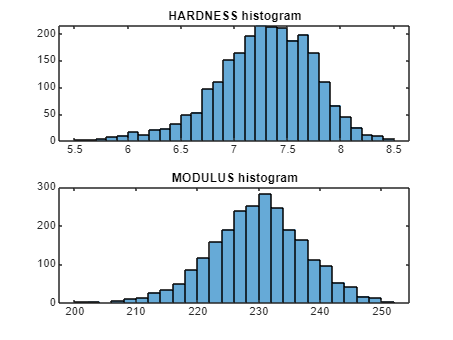

subplot(2,1,1)
histogram(cleandata.HARDNESS)
title("HARDNESS histogram")

subplot(2,1,2)
histogram(cleandata.MODULUS)
title("MODULUS histogram")

### Contour plots

% Ordenar X e Y en orden ascendente
X_sorted = sort(unique(cleandata.XPosition));
Y_sorted = sort(unique(cleandata.YPosition));

% Definir la cuadrícula para la interpolación
[x_grid, y_grid] = meshgrid(X_sorted, Y_sorted);

% Interpolar HARDNESS
Z1_interpolated = griddata(cleandata.XPosition, cleandata.YPosition, cleandata.HARDNESS, x_grid, y_grid, 'linear');

% Interpolar MODULUS
Z2_interpolated = griddata(cleandata.XPosition, cleandata.YPosition, cleandata.MODULUS, x_grid, y_grid, 'linear');

% Define the limit values of the hardness (1) and modulus (2) contour plots
vmin1 = 5.5;
vmax1 = 8.5;
vmin2 = 190;
vmax2 = 245;

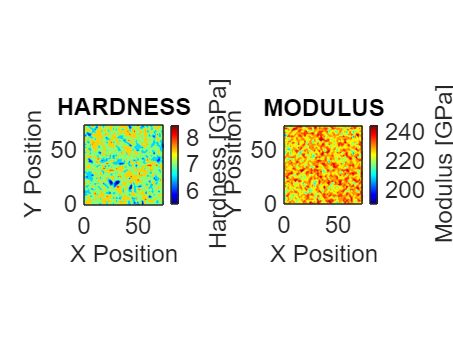

% HARDNESS contour plot
subplot(1, 2, 1);

% Recortar los valores interpolados según vmin/vmax
Z1_matrix_clipped = min(max(Z1_interpolated, vmin1), vmax1);

% Crear el gráfico de contorno lleno (contourf)
contourf(X_sorted, Y_sorted, Z1_matrix_clipped, 'LineStyle', 'none');

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin1, vmax1]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título del subplot
title('HARDNESS', 'FontSize', 18);

axis equal

% MODULUS contour plot
subplot(1, 2, 2);

% Recortar los valores interpolados según vmin/vmax
Z2_matrix_clipped = min(max(Z2_interpolated, vmin2), vmax2);

% Crear el gráfico de contorno lleno (contourf)
contourf(X_sorted, Y_sorted, Z2_matrix_clipped, 'LineStyle', 'none');

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin2, vmax2]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título del subplot
title('MODULUS', 'FontSize', 18);

axis equal

Gráfico de píxeles

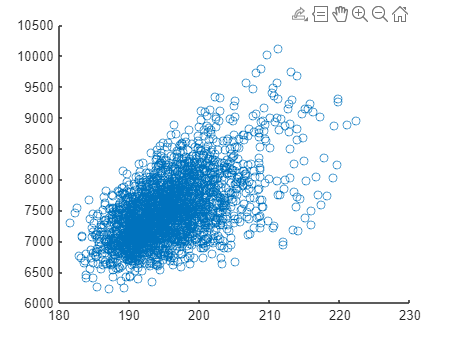

% HARDNESS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(X_sorted, Y_sorted, Z1_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin1, vmax1]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título
title('HARDNESS', 'FontSize', 18);

axis equal

% MODULUS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(X_sorted, Y_sorted, Z2_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin3, vmax3]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título
title('MODULUS', 'FontSize', 18);

axis equal

# 4D mapping

clear all

% Import data from spreadsheet
excel_file = readtable("C:\Users\franc\Documents\Trabajo\Colaboraciones\Mariana Pinto\Francesc_20250321_2\27Co_150x150_4D.xlsx", "Sheet", "Test 1", "TextType", "string");

% Display results
excel_file

excel_file = 135000×9 table
        Markers        INDENT    X      Y        DEPTH        LOAD       STIFFNESS     HARDNESS    MODULUS
    _______________    ______    _    ______    _______    __________    __________    ________    _______

    "Surface Index"     NaN      0         0    -4.2222    0.00081709           NaN        NaN        NaN 
    <missing>             1      0         0     15.513       0.23156         35835     29.383     473.35 
    <missing>             1      0         0     35.567        0.9472         74812     34.683     561.83 
    <missing>             1      0         0     55.533        2.1228    1.2216e+05      34.61     643.21 
    <missing>          

Eliminate rows that contain NaN values in HARDNESS or MODULUS columns.

excel_file = excel_file(~isnan(excel_file.INDENT), :);
rowswithNaN=isnan(excel_file.HARDNESS) | isnan(excel_file.MODULUS);
cleandata=excel_file(~rowswithNaN,:);
% Eliminar la primera fila (encabezados)
cleandata(1, :) = [];


depthlevel = 5; % Número de fila a seleccionar en cada grupo de INDENT
    
    % Obtener los grupos únicos de INDENT
    uniqueIndents = unique(excel_file.INDENT);
    cleandata = [];

    for i = 1:length(uniqueIndents)
        groupData = excel_file(excel_file.INDENT == uniqueIndents(i), :);
        if height(groupData) >= depthlevel
            cleandata = [cleandata; groupData(depthlevel, :)];
        else
            % Si no hay suficientes filas en el grupo, tomar la última disponible
            cleandata = [cleandata; groupData(end, :)];
        end
    end

Histograms

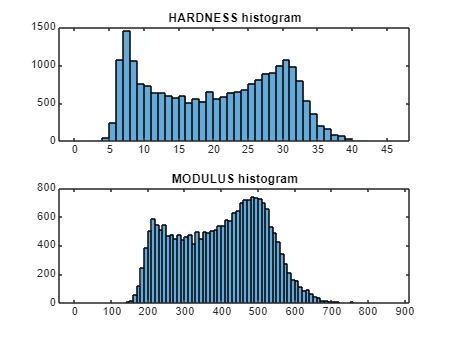

subplot(2,1,1)
histogram(cleandata.HARDNESS)
title("HARDNESS histogram")

subplot(2,1,2)
histogram(cleandata.MODULUS)
title("MODULUS histogram")

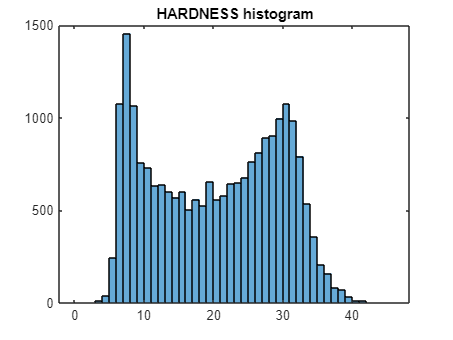

figure
histogram(cleandata.HARDNESS)
title("HARDNESS histogram")

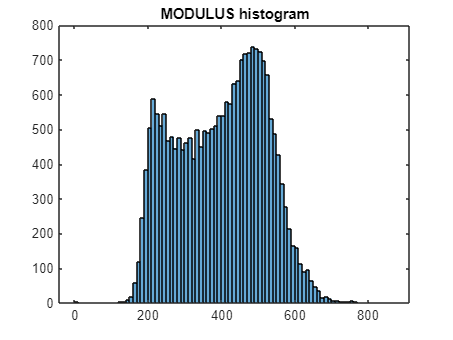


figure
histogram(cleandata.MODULUS)
title("MODULUS histogram")

### Contour plots

% Ordenar X e Y en orden ascendente
X_sorted = sort(unique(cleandata.X));
Y_sorted = sort(unique(cleandata.Y));

% Definir la cuadrícula para la interpolación
[x_grid, y_grid] = meshgrid(X_sorted, Y_sorted);

% Interpolar HARDNESS
Z1_interpolated = griddata(cleandata.X, cleandata.Y, cleandata.HARDNESS, x_grid, y_grid, 'linear');

% Interpolar MODULUS
Z2_interpolated = griddata(cleandata.X, cleandata.Y, cleandata.MODULUS, x_grid, y_grid, 'linear');

% Define the limit values of the hardness (1) and modulus (2) contour plots
vmin1 = 5;
vmax1 = 40;
vmin2 = 140;
vmax2 = 700;

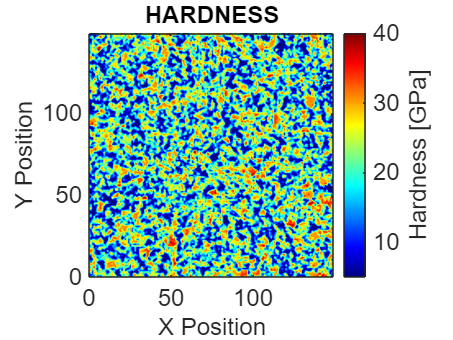

levels = 10;

% HARDNESS contour plot
figure

% Recortar los valores interpolados según vmin/vmax
Z1_matrix_clipped = min(max(Z1_interpolated, vmin1), vmax1);

% Crear el gráfico de contorno lleno (contourf)
contourf(X_sorted, Y_sorted, Z1_matrix_clipped, levels, 'LineStyle', 'none');

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin1, vmax1]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título del subplot
title('HARDNESS', 'FontSize', 18);

axis equal

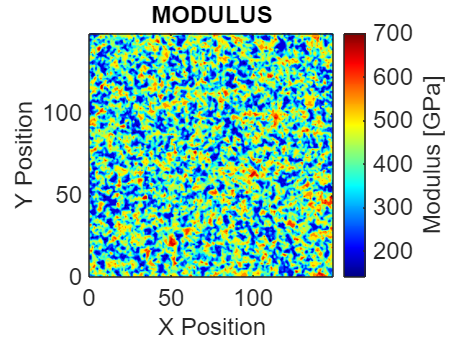


% MODULUS contour plot
figure

% Recortar los valores interpolados según vmin/vmax
Z2_matrix_clipped = min(max(Z2_interpolated, vmin2), vmax2);

% Crear el gráfico de contorno lleno (contourf)
contourf(X_sorted, Y_sorted, Z2_matrix_clipped, levels,'LineStyle', 'none');

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin2, vmax2]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título del subplot
title('MODULUS', 'FontSize', 18);

axis equal

Gráfico de píxeles

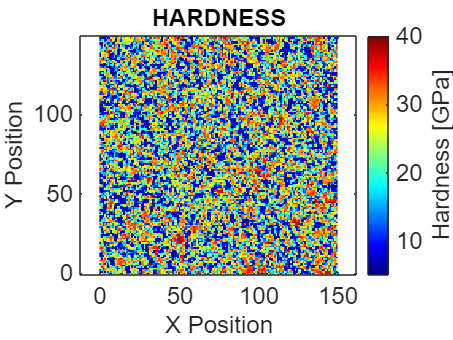

% HARDNESS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(X_sorted, Y_sorted, Z1_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin1, vmax1]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título
title('HARDNESS', 'FontSize', 18);

axis equal

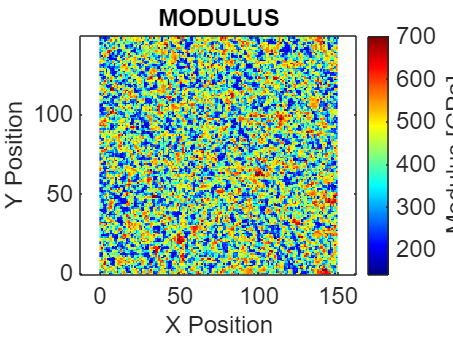


% MODULUS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(X_sorted, Y_sorted, Z2_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin2, vmax2]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);

% Establecer el título
title('MODULUS', 'FontSize', 18);

axis equal